## **Worked Example 1.2**

 AERO60007 Control Systems 2024-2025

% Housekeeping
clear
clc
close all

% Input the a, b, c and d values
a = 1;
b = 1;
c = 1;
d = 0;

% Construct a state-space system using the ss(A,B,C,D) command
sys = ss(a, b, c, d);

% Input the initial condition value
x0 = 1;

% Define the desired time interval T for simulation
% in this case T ranges from 0s to 6s in intervals of 0.001s 
T = [0 : 0.001 : 6];

% Define the value of the open-loop input at each time interval 
U_ol = -2 .* exp(-T);

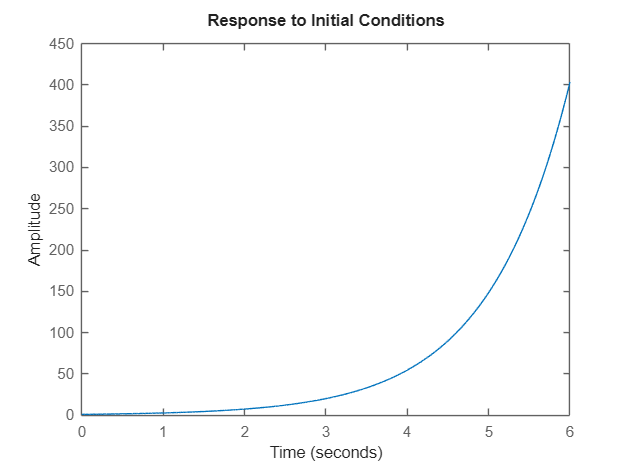

% Simulate the dynamical system with zero input force and initial condition 𝑥
% using the intial(sys,x0,T) command
initial(sys, x0, T)

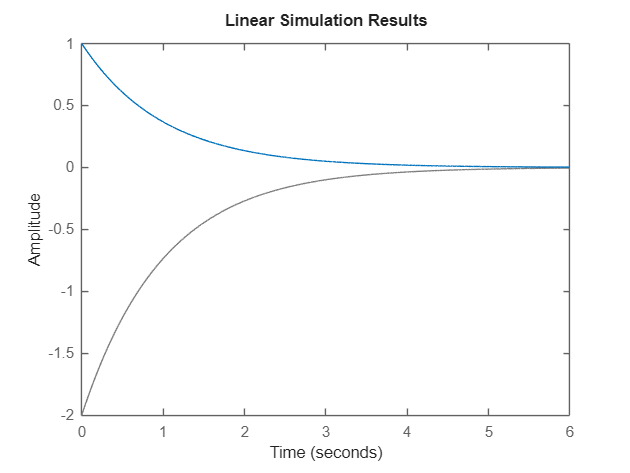

% Simulate the dynamical system with the open-loop input
% using the lsim(sys,U,T,x0) command
lsim(sys, U_ol, T, x0)

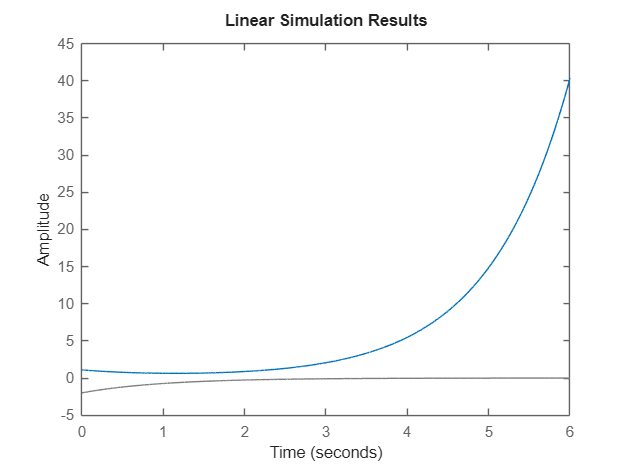

% Simulate the dynamical system with the open-loop input and an initial condition error
lsim(sys, U_ol, T, 1.1 * x0)

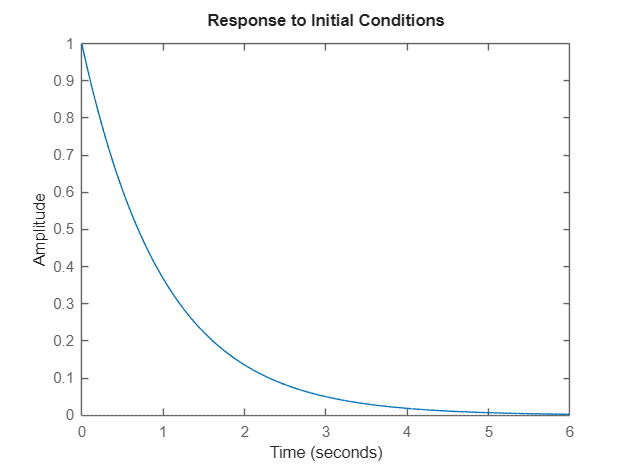

% Input the closed-loop a, b, c and d values and construct a closed-loop state-space system
a_cl = -1; 
b_cl = 0; 
c_cl = 1; 
d_cl = 0; 
sys_cl = ss(a_cl, b_cl, c_cl, d_cl);

% Simulate the closed-loop system
initial(sys_cl, x0, T)

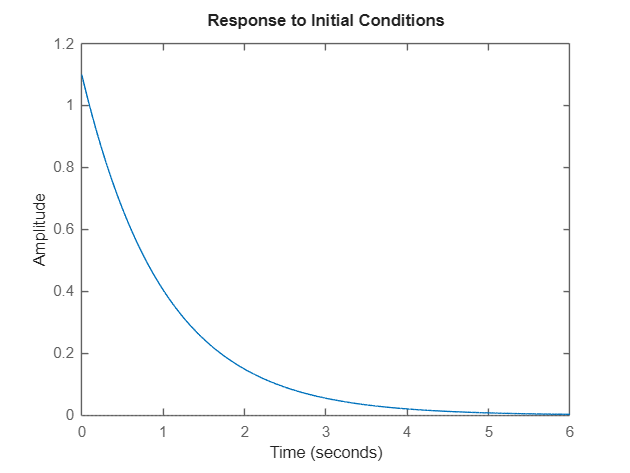

% Simulate the closed-loop system with an initial condition error
initial(sys_cl, 1.1 * x0, T)